## **Internal Cross Validation of Multiple Linear Regression Model - Main Sample (HCP) - controlled for TIV **

## **Part 1: Internal Cross Validation of Multiple Linear Regression Model  **

This  is Part 1 of the Internal Cross Validation of the Multiple Linear Regression Model. It partitions the sample into 5 different folds and creates the positive and negative NMAs for each training fold and test fold based on the correllation with intelligence.

Before Running this script:

- all scripts in HCP Data Prep 

- run HCP_compute_coupling meaures

- run HCP_control_for_TIV

**1) Create a cell that contains for each subject a vector of 8 predictors for each node **

for i = 1:1030
    x = final_r_all_HCP_1030_new{i,1};
    for j = 1:358
        Node_all_baseline_best_measures_HCP_weighted_only{i,j} = x(j,:);
    end
end


**2) Create cell that contains information from all subjects and all coupling measures for all nodes separetely (1030*8)**

% extract for each collumn 8 rows from each row and put them together in a matrix (--> I need 1030*16 Matrix for each Node)

n = size(Node_all_baseline_best_measures_HCP_weighted_only,2);
All_Nodes_complete_baseline_best_measures_HCP_weighted_only = cell(1,n);
for j = 1:n
    All_Nodes_complete_baseline_best_measures_HCP_weighted_only{j} = vertcat(Node_all_baseline_best_measures_HCP_weighted_only{:,j});
end

**3) Split into 5 folds **

**Create a Loop to Do the Partition 100 times **

for cross_validation_round = 1:100;
    display(cross_validation_round)

cross_validation_round = 1

cross_validation_round = 2

cross_validation_round = 3

cross_validation_round = 4

cross_validation_round = 5

cross_validation_round = 6

cross_validation_round = 7

cross_validation_round = 8

cross_validation_round = 9

cross_validation_round = 10

cross_validation_round = 11

cross_validation_round = 12

cross_validation_round = 13

cross_validation_round = 14

cross_validation_round = 15

cross_validation_round = 16

cross_validation_round = 17

cross_validation_round = 18

cross_validation_round = 19

cross_validation_round = 20

cross_validation_round = 21

cross_validation_round = 22

cross_validation_round = 23

cross_validation_round = 24

cross_validation_round = 25

cross_validation_round = 26

cross_validation_round = 27

cross_validation_round = 28

cross_validation_round = 29

cross_validation_round = 30

cross_validation_round = 31

cross_validation_round = 32

cross_validation_round = 33

cross_validation_round = 34

cross_validation_round = 35

cross_validation_round = 36

cross_validation_round = 37

cross_validation_round = 38

cross_validation_round = 39

cross_validation_round = 40

cross_validation_round = 41

cross_validation_round = 48

cross_validation_round = 49

cross_validation_round = 50

cross_validation_round = 51

cross_validation_round = 52

cross_validation_round = 53

cross_validation_round = 54

cross_validation_round = 55

cross_validation_round = 56

cross_validation_round = 57

cross_validation_round = 58

cross_validation_round = 59

cross_validation_round = 60

cross_validation_round = 61

cross_validation_round = 62

cross_validation_round = 63

cross_validation_round = 74

cross_validation_round = 75

cross_validation_round = 76

cross_validation_round = 77

cross_validation_round = 78

cross_validation_round = 79

cross_validation_round = 80

cross_validation_round = 92

cross_validation_round = 93

cross_validation_round = 94

cross_validation_round = 95

cross_validation_round = 96

cross_validation_round = 97

cross_validation_round = 98

cross_validation_round = 99

cross_validation_round = 100

## **Create Cross-Validation Partition based on Family IQ**

This script creates a partition for the internal cross validation of the linear regression model that is stratified based on Family IQ. That way, we respect the family structures in the HCP and create a distribution of subjects in the test and training samples that is not biased towards intelligence scores. 

3.1) Assign the variables

    HCP_family_ID = HCP_behavioral_1030.Family_ID;
    HCP_Subject_names = HCP_behavioral_1030.Subject_ID;
    HCP_g_score = HCP_behavioral_1030.G_Factor;

3.2) Create a table containing all the information that I need 

    [number_of_families,~,family_group_number] = unique(HCP_behavioral_1030.Family_ID); % tells me which subject belongs to which family --> Indices


    for i = 1:431 % because there is 431 familys in the sample (unique output 1)

        indices_for_same_family = find(family_group_number == i);
        subject_ID_same_fam = HCP_Subject_names(indices_for_same_family);
        family_ID_original = HCP_family_ID(indices_for_same_family);
        g_score_same_fam = HCP_g_score(indices_for_same_family);

        family_info_HCP{i,1} = i;
        family_info_HCP{i,2} = family_ID_original;
        family_info_HCP{i,3} = indices_for_same_family;
        family_info_HCP{i,4} = subject_ID_same_fam;
        family_info_HCP{i,5} = g_score_same_fam;

    end

3.3) Create a Family IQ

    for i = 1:431
        family_IQ_separate = family_info_HCP{i,5};
        family_IQ_average = mean(family_IQ_separate);
        family_info_HCP{i,6} = family_IQ_average;
    end

3.4) Convert cell to table

    family_info_HCP_table = cell2table(family_info_HCP);
    family_info_HCP_table.Properties.VariableNames = {'Group Number','Original_Family_ID', 'Indices_for_same_Family', 'Subject_ID_same_fam', 'g_score_separate_same_fam', 'Mean_g_score_same_fam'};

3.5) Create a CV partition based on Family IQ (for the families) 

    Intelligence = family_info_HCP_table.Mean_g_score_same_fam;


    Intelligence_for_cv_partition_1 = rescale(Intelligence,1,30);
    Intelligence_for_cv_partition = int16(Intelligence_for_cv_partition_1); % create 30 groups to ultimatly create a stratified cv partition


    c = cvpartition(Intelligence_for_cv_partition,'KFold',5);

3.6) Create output: indices for the families

    % Train 1 & Test 1

    index_test_1 = find(test(c,1));
    index_train_1 = find(training(c,1));

    % Train 2 & Test 2
    index_test_2 = find(test(c,2));
    index_train_2 = find(training(c,2));

    % Train 3 & Test 3

    index_test_3 = find(test(c,3));
    index_train_3 = find(training(c,3));

    % Train 4 & Test 4

    index_test_4 = find(test(c,4));
    index_train_4 = find(training(c,4));

    % Train 5 & Test 5

    index_test_5 = find(test(c,5));
    index_train_5 = find(training(c,5));


3.7) Reassign the individual subjects back into the groups from the partition 

    % Train 1 & Test 1 

    test_1 = family_info_HCP_table.Indices_for_same_Family(index_test_1);
    index_test_1_fam = cat(1,test_1{:,1});
    index_test_1_fam = sort(index_test_1_fam,"ascend");

    train_1 = family_info_HCP_table.Indices_for_same_Family(index_train_1);
    index_train_1_fam = cat(1,train_1{:,1});
    index_train_1_fam = sort(index_train_1_fam,"ascend");

    % Train 2 & Test 2 

    test_2 = family_info_HCP_table.Indices_for_same_Family(index_test_2);
    index_test_2_fam = cat(1,test_2{:,1});
    index_test_2_fam = sort(index_test_2_fam,"ascend");

    train_2 = family_info_HCP_table.Indices_for_same_Family(index_train_2);
    index_train_2_fam = cat(1,train_2{:,1});
    index_train_2_fam = sort(index_train_2_fam,"ascend");


    % Train 3 & Test 3 

    test_3 = family_info_HCP_table.Indices_for_same_Family(index_test_3);
    index_test_3_fam = cat(1,test_3{:,1});
    index_test_3_fam = sort(index_test_3_fam,"ascend");

    train_3 = family_info_HCP_table.Indices_for_same_Family(index_train_3);
    index_train_3_fam = cat(1,train_3{:,1});
    index_train_3_fam = sort(index_train_3_fam,"ascend");


    % Train 4 & Test 4 

    test_4 = family_info_HCP_table.Indices_for_same_Family(index_test_4);
    index_test_4_fam = cat(1,test_4{:,1});
    index_test_4_fam = sort(index_test_4_fam,"ascend");

    train_4 = family_info_HCP_table.Indices_for_same_Family(index_train_4);
    index_train_4_fam = cat(1,train_4{:,1});
    index_train_4_fam = sort(index_train_4_fam,"ascend");


    % Train 5 & Test 5 

    test_5 = family_info_HCP_table.Indices_for_same_Family(index_test_5);
    index_test_5_fam = cat(1,test_5{:,1});
    index_test_5_fam = sort(index_test_5_fam,"ascend");

    train_5 = family_info_HCP_table.Indices_for_same_Family(index_train_5);
    index_train_5_fam = cat(1,train_5{:,1});
    index_train_5_fam = sort(index_train_5_fam,"ascend");


**4) Divide Data in Test and Training Samples **

4.1)  Divide the coupling data into 5 Training and 5 Test Samples

    for i = 1:358
        all_data_node = All_Nodes_complete_baseline_best_measures_HCP_weighted_only{1,i};

        Node_training_sample_1 = all_data_node(index_train_1_fam,:);
        Node_test_sample_1 = all_data_node(index_test_1_fam,:);

        Node_training_sample_2 = all_data_node(index_train_2_fam,:);
        Node_test_sample_2 = all_data_node(index_test_2_fam,:);

        Node_training_sample_3 = all_data_node(index_train_3_fam,:);
        Node_test_sample_3 = all_data_node(index_test_3_fam, :);

        Node_training_sample_4 = all_data_node(index_train_4_fam,:);
        Node_test_sample_4 = all_data_node(index_test_4_fam,:);

        Node_training_sample_5 = all_data_node(index_train_5_fam,:);
        Node_test_sample_5 = all_data_node(index_test_5_fam, :);

        All_Nodes_complete_cross_validation_HCP_baseline_weighted_only{1,i} = Node_training_sample_1;
        All_Nodes_complete_cross_validation_HCP_baseline_weighted_only{2,i} = Node_training_sample_2;
        All_Nodes_complete_cross_validation_HCP_baseline_weighted_only{3,i} = Node_training_sample_3;
        All_Nodes_complete_cross_validation_HCP_baseline_weighted_only{4,i} = Node_training_sample_4;
        All_Nodes_complete_cross_validation_HCP_baseline_weighted_only{5,i} = Node_training_sample_5;
        All_Nodes_complete_cross_validation_HCP_baseline_weighted_only{6,i} = Node_test_sample_1;
        All_Nodes_complete_cross_validation_HCP_baseline_weighted_only{7,i} = Node_test_sample_2;
        All_Nodes_complete_cross_validation_HCP_baseline_weighted_only{8,i} = Node_test_sample_3;
        All_Nodes_complete_cross_validation_HCP_baseline_weighted_only{9,i} = Node_test_sample_4;
        All_Nodes_complete_cross_validation_HCP_baseline_weighted_only{10,i} = Node_test_sample_5;

    end

4.2) Divide Intelligence into 5 Training Samples & 5 Test Samples

    Intelligence = HCP_behavioral_1030.G_Factor;

    Intelligence_train_1 = Intelligence(index_train_1_fam,:);
    Intelligence_train_2 = Intelligence(index_train_2_fam,:);
    Intelligence_train_3 = Intelligence(index_train_3_fam,:);
    Intelligence_train_4 = Intelligence(index_train_4_fam,:);
    Intelligence_train_5 = Intelligence(index_train_5_fam,:);

    Intelligence_test_1 = Intelligence(index_test_1_fam,:);
    Intelligence_test_2 = Intelligence(index_test_2_fam,:);
    Intelligence_test_3 = Intelligence(index_test_3_fam,:);
    Intelligence_test_4 = Intelligence(index_test_4_fam,:);
    Intelligence_test_5 = Intelligence(index_test_5_fam,:);

    Intelligence_training_samples{1,:} = Intelligence_train_1;
    Intelligence_training_samples{2,:} = Intelligence_train_2;
    Intelligence_training_samples{3,:} = Intelligence_train_3;
    Intelligence_training_samples{4,:} = Intelligence_train_4;
    Intelligence_training_samples{5,:} = Intelligence_train_5;

    Intelligence_test_samples{1,:} = Intelligence_test_1;
    Intelligence_test_samples{2,:} = Intelligence_test_2;
    Intelligence_test_samples{3,:} = Intelligence_test_3;
    Intelligence_test_samples{4,:} = Intelligence_test_4;
    Intelligence_test_samples{5,:} = Intelligence_test_5;

4.3)  Divide Confounding Variables into 5 Training Samples & 5 Test Samples

    ALter = HCP_behavioral_1030.Age;

    ALter_train_1 = ALter(index_train_1_fam,:);
    ALter_train_2 = ALter(index_train_2_fam,:);
    ALter_train_3 = ALter(index_train_3_fam,:);
    ALter_train_4 = ALter(index_train_4_fam,:);
    ALter_train_5 = ALter(index_train_5_fam,:);

    ALter_test_1 = ALter(index_test_1_fam,:);
    ALter_test_2 = ALter(index_test_2_fam,:);
    ALter_test_3 = ALter(index_test_3_fam,:);
    ALter_test_4 = ALter(index_test_4_fam,:);
    ALter_test_5 = ALter(index_test_5_fam, :);


    ALter_training_samples{1,:} = ALter_train_1;
    ALter_training_samples{2,:} = ALter_train_2;
    ALter_training_samples{3,:} = ALter_train_3;
    ALter_training_samples{4,:} = ALter_train_4;
    ALter_training_samples{5,:} = ALter_train_5;

    ALter_test_samples{1,:} = ALter_test_1;
    ALter_test_samples{2,:} = ALter_test_2;
    ALter_test_samples{3,:} = ALter_test_3;
    ALter_test_samples{4,:} = ALter_test_4;
    ALter_test_samples{5,:} = ALter_test_5;

    Gender = HCP_behavioral_1030.("Gender num");

    Gender_train_1 = Gender(index_train_1_fam,:);
    Gender_train_2 = Gender(index_train_2_fam,:);
    Gender_train_3 = Gender(index_train_3_fam,:);
    Gender_train_4 = Gender(index_train_4_fam,:);
    Gender_train_5 = Gender(index_train_5_fam,:);

    Gender_test_1 = Gender(index_test_1_fam,:);
    Gender_test_2 = Gender(index_test_2_fam,:);
    Gender_test_3 = Gender(index_test_3_fam,:);
    Gender_test_4 = Gender(index_test_4_fam,:);
    Gender_test_5 = Gender(index_test_5_fam,:);

    Gender_training_samples{1,:} = Gender_train_1;
    Gender_training_samples{2,:} = Gender_train_2;
    Gender_training_samples{3,:} = Gender_train_3;
    Gender_training_samples{4,:} = Gender_train_4;
    Gender_training_samples{5,:} = Gender_train_5;

    Gender_test_samples{1,:} = Gender_test_1;
    Gender_test_samples{2,:} = Gender_test_2;
    Gender_test_samples{3,:} = Gender_test_3;
    Gender_test_samples{4,:} = Gender_test_4;
    Gender_test_samples{5,:} = Gender_test_5;

    meanFDJenk = HCP_behavioral_1030.Mean_mean_FD;

    meanFDJenk_train_1 = meanFDJenk(index_train_1_fam,:);
    meanFDJenk_train_2 = meanFDJenk(index_train_2_fam,:);
    meanFDJenk_train_3 = meanFDJenk(index_train_3_fam,:);
    meanFDJenk_train_4 = meanFDJenk(index_train_4_fam,:);
    meanFDJenk_train_5 = meanFDJenk(index_train_5_fam,:);

    meanFDJenk_test_1 = meanFDJenk(index_test_1_fam,:);
    meanFDJenk_test_2 = meanFDJenk(index_test_2_fam,:);
    meanFDJenk_test_3 = meanFDJenk(index_test_3_fam, :);
    meanFDJenk_test_4 = meanFDJenk(index_test_4_fam,:);
    meanFDJenk_test_5 = meanFDJenk(index_test_5_fam, :);


    meanFDJenk_training_samples{1,:} = meanFDJenk_train_1;
    meanFDJenk_training_samples{2,:} = meanFDJenk_train_2;
    meanFDJenk_training_samples{3,:} = meanFDJenk_train_3;
    meanFDJenk_training_samples{4,:} = meanFDJenk_train_4;
    meanFDJenk_training_samples{5,:} = meanFDJenk_train_5;

    meanFDJenk_test_samples{1,:} = meanFDJenk_test_1;
    meanFDJenk_test_samples{2,:} = meanFDJenk_test_2;
    meanFDJenk_test_samples{3,:} = meanFDJenk_test_3;
    meanFDJenk_test_samples{4,:} = meanFDJenk_test_4;
    meanFDJenk_test_samples{5,:} = meanFDJenk_test_5;

    LQ = HCP_behavioral_1030.Handedness;

    LQ_train_1 = LQ(index_train_1_fam,:);
    LQ_train_2 = LQ(index_train_2_fam,:);
    LQ_train_3 = LQ(index_train_3_fam,:);
    LQ_train_4 = LQ(index_train_4_fam,:);
    LQ_train_5 = LQ(index_train_5_fam,:);

    LQ_test_1 = LQ(index_test_1_fam,:);
    LQ_test_2 = LQ(index_test_2_fam,:);
    LQ_test_3 = LQ(index_test_3_fam,:);
    LQ_test_4 = LQ(index_test_4_fam,:);
    LQ_test_5 = LQ(index_test_5_fam,:);


    LQ_training_samples{1,:} = LQ_train_1;
    LQ_training_samples{2,:} = LQ_train_2;
    LQ_training_samples{3,:} = LQ_train_3;
    LQ_training_samples{4,:} = LQ_train_4;
    LQ_training_samples{5,:} = LQ_train_5;

    LQ_test_samples{1,:} = LQ_test_1;
    LQ_test_samples{2,:} = LQ_test_2;
    LQ_test_samples{3,:} = LQ_test_3;
    LQ_test_samples{4,:} = LQ_test_4;
    LQ_test_samples{5,:} = LQ_test_5;

    TIV = HCP_behavioral_1030_with_brain_size.FS_IntraCranial_Vol;

    TIV_train_1 = TIV(index_train_1_fam,:);
    TIV_train_2 = TIV(index_train_2_fam,:);
    TIV_train_3 = TIV(index_train_3_fam,:);
    TIV_train_4 = TIV(index_train_4_fam,:);
    TIV_train_5 = TIV(index_train_5_fam,:);

    TIV_test_1 = TIV(index_test_1_fam,:);
    TIV_test_2 = TIV(index_test_2_fam,:);
    TIV_test_3 = TIV(index_test_3_fam,:);
    TIV_test_4 = TIV(index_test_4_fam,:);
    TIV_test_5 = TIV(index_test_5_fam,:);


    TIV_training_samples{1,:} = TIV_train_1;
    TIV_training_samples{2,:} = TIV_train_2;
    TIV_training_samples{3,:} = TIV_train_3;
    TIV_training_samples{4,:} = TIV_train_4;
    TIV_training_samples{5,:} = TIV_train_5;

    TIV_test_samples{1,:} = TIV_test_1;
    TIV_test_samples{2,:} = TIV_test_2;
    TIV_test_samples{3,:} = TIV_test_3;
    TIV_test_samples{4,:} = TIV_test_4;
    TIV_test_samples{5,:} = TIV_test_5;

**5) Build a positive and negative Node Measure Assignment (NMA) for each Training Fold**

5.1) Build a correlation matrix for each training fold 


    for fold = 1:5

        Correlation_com_measures_fold_rho = zeros(358,8); % Preallocation
        Correlation_com_measure_fold_pval = zeros(358,8); % Preallocation

        for i = 1:358 % mache das für jede Node Extra
            All_Communication_measures_per_node = All_Nodes_complete_cross_validation_HCP_baseline_weighted_only{fold,i};

            for p = 1:8 % jetzt jedes communication measure mit Intelligenz korrelieren
                Communication_Measure_separate = All_Communication_measures_per_node(:,p);

                % Correlation

                x = [Communication_Measure_separate, Intelligence_training_samples{fold}];
                z = [ALter_training_samples{fold}, Gender_training_samples{fold}, meanFDJenk_training_samples{fold}, LQ_training_samples{fold}, TIV_training_samples{fold}]; % control variables

                [rho,pval] = partialcorr(x,z);

                rho = rho(1,2);
                pval = pval(1,2);

                Correlation_com_measures_fold_rho(i,p) = rho;
                Correlation_com_measure_fold_pval(i,p) = pval;


            end
        end

        Correlation_matrices_all_folds{fold,1} = Correlation_com_measures_fold_rho;
        Correlation_matrices_all_folds{fold,2} = Correlation_com_measure_fold_pval;
    end

5.2) Build positive and negative NMA for each training sample 

5.2.1) Find out which ones correlate the most positive with intelligence 

    for fold = 1:5
        Correlation_com_measures_fold_rho = Correlation_matrices_all_folds{fold,1};
        for i = 1:358
            Correlation_rho_per_node = Correlation_com_measures_fold_rho(i,:);
            Max_Rho = max(Correlation_rho_per_node);
            Idx_max_rho = find(Correlation_rho_per_node == Max_Rho);
            Info_best_performing_communication_measure_pos_train_rho{i,1} = Max_Rho;
            Info_best_performing_communication_measure_pos_train_idx{i,1} = Idx_max_rho;
        end
        Pos_NMA_all_fold{fold,1} = Info_best_performing_communication_measure_pos_train_rho;
        Pos_NMA_all_fold{fold,2} = Info_best_performing_communication_measure_pos_train_idx;
    end

5.2.2) Find out which ones correlate the most negative with intelligence

    for fold = 1:5
        Correlation_com_measures_fold_rho = Correlation_matrices_all_folds{fold,1};

        for i = 1:358
            Correlation_rho_per_node = Correlation_com_measures_fold_rho(i,:);
            Min_Rho = min(Correlation_rho_per_node);
            Idx_min_rho = find(Correlation_rho_per_node == Min_Rho);
            Info_best_performing_communication_measure_neg_train_rho{i,1} = Min_Rho;
            Info_best_performing_communication_measure_neg_train_idx{i,1} = Idx_min_rho;
        end
        Neg_NMA_all_fold{fold,1} = Info_best_performing_communication_measure_neg_train_rho;
        Neg_NMA_all_fold{fold,2} = Info_best_performing_communication_measure_neg_train_idx;
    end

5.3) Define Sizes of Training Samples and Test Samples 

    size_training_sample_1 = size(All_Nodes_complete_cross_validation_HCP_baseline_weighted_only{1,1},1);
    size_training_sample_2 = size(All_Nodes_complete_cross_validation_HCP_baseline_weighted_only{2,1},1);
    size_training_sample_3 = size(All_Nodes_complete_cross_validation_HCP_baseline_weighted_only{3,1},1);
    size_training_sample_4 = size(All_Nodes_complete_cross_validation_HCP_baseline_weighted_only{4,1},1);
    size_training_sample_5 = size(All_Nodes_complete_cross_validation_HCP_baseline_weighted_only{5,1},1);

    size_test_sample_1 = size(All_Nodes_complete_cross_validation_HCP_baseline_weighted_only{6,1},1);
    size_test_sample_2 = size(All_Nodes_complete_cross_validation_HCP_baseline_weighted_only{7,1},1);
    size_test_sample_3 = size(All_Nodes_complete_cross_validation_HCP_baseline_weighted_only{8,1},1);
    size_test_sample_4 = size(All_Nodes_complete_cross_validation_HCP_baseline_weighted_only{9,1},1);
    size_test_sample_5 = size(All_Nodes_complete_cross_validation_HCP_baseline_weighted_only{10,1},1);

    size_training_test_samples{1,1} = size_training_sample_1;
    size_training_test_samples{2,1} = size_training_sample_2;
    size_training_test_samples{3,1} = size_training_sample_3;
    size_training_test_samples{4,1} = size_training_sample_4;
    size_training_test_samples{5,1} = size_training_sample_5;

    size_training_test_samples{1,2} = size_test_sample_1;
    size_training_test_samples{2,2} = size_test_sample_2;
    size_training_test_samples{3,2} = size_test_sample_3;
    size_training_test_samples{4,2} = size_test_sample_4;
    size_training_test_samples{5,2} = size_test_sample_5;

5.4) Extract the NMA values for the positive NMA

    for fold = 1:5

        size_sample = size_training_test_samples{fold,1};
        Best_case_scenario_r_values_pos_train = zeros(358,size_sample);
        best_performing_measure_per_node_pos = cell2mat(Pos_NMA_all_fold{fold,2});

        for i = 1:358
            index = best_performing_measure_per_node_pos(i);
            Best_scenario_node_values_pos = All_Nodes_complete_cross_validation_HCP_baseline_weighted_only{fold,i}(:,index);
            Best_case_scenario_r_values_pos_train(i,:) = Best_scenario_node_values_pos';
        end

        Best_case_scenario_r_values_pos_train = Best_case_scenario_r_values_pos_train';

        Best_case_scenario_training_samples{fold,1} = Best_case_scenario_r_values_pos_train;

    end

5.5) Extract the NMA values for the negative NMA

    for fold = 1:5

        size_sample = size_training_test_samples{fold,1};
        Best_case_scenario_r_values_neg_train = zeros(358,size_sample);
        best_performing_measure_per_node_neg = cell2mat(Neg_NMA_all_fold{fold,2});

        for i = 1:358
            index = best_performing_measure_per_node_neg(i);
            Best_scenario_node_values_neg = All_Nodes_complete_cross_validation_HCP_baseline_weighted_only{fold,i}(:,index);
            Best_case_scenario_r_values_neg_train(i,:) = Best_scenario_node_values_neg';
        end

        Best_case_scenario_r_values_neg_train = Best_case_scenario_r_values_neg_train';

        Best_case_scenario_training_samples{fold,2} = Best_case_scenario_r_values_neg_train;

    end

**6) Build a positive and negative Node Measure Assignment (NMA) for each Test Fold**

6.1) Extract the NMA values for the positive NMA

    for fold = 1:5
        size_sample = size_training_test_samples{fold,2};
        Best_case_scenario_r_values_pos_test = zeros(358,size_sample);
        best_performing_measure_per_node_pos = cell2mat(Pos_NMA_all_fold{fold,2});
        index_into_crossvall = fold+5;

        for i = 1:358
            index = best_performing_measure_per_node_pos(i);
            Best_scenario_node_values_pos = All_Nodes_complete_cross_validation_HCP_baseline_weighted_only{index_into_crossvall,i}(:,index);
            Best_case_scenario_r_values_pos_test(i,:) = Best_scenario_node_values_pos';
        end

        Best_case_scenario_r_values_pos_test = Best_case_scenario_r_values_pos_test';

        Best_case_scenario_test_samples{fold,1} = Best_case_scenario_r_values_pos_test;

    end

6.2) Extract the NMA values for the negative NMA

    for fold = 1:5
        size_sample = size_training_test_samples{fold,2};
        Best_case_scenario_r_values_neg_test = zeros(358,size_sample);
        best_performing_measure_per_node_neg = cell2mat(Neg_NMA_all_fold{fold,2});
        index_into_crossvall = fold+5;

        for i = 1:358
            index = best_performing_measure_per_node_neg(i);
            Best_scenario_node_values_neg = All_Nodes_complete_cross_validation_HCP_baseline_weighted_only{index_into_crossvall,i}(:,index);
            Best_case_scenario_r_values_neg_test(i,:) = Best_scenario_node_values_neg';
        end

        Best_case_scenario_r_values_neg_test = Best_case_scenario_r_values_neg_test';

        Best_case_scenario_test_samples{fold,2} = Best_case_scenario_r_values_neg_test;

    end



## **Part 2: Internal Cross Validation of Multiple Linear Regression**

This  is Part 2 of the Cross Validation of the Multiple Linear Regression Model. It uses the Node-Measure Assignments that were created above 

to build multiple linear regression models that are then tested in the test sample. This time, we also control for TIV. 

**1) Build the Models for the Training Samples **

Training Sample 1

Convert scores into z-scores

    Alter_train_1_z = normalize(ALter_train_1);
    Gender_train_1_z = normalize(Gender_train_1);
    meanFDJenk_train_1_z = normalize(meanFDJenk_train_1);
    LQ_train_1_z = normalize(LQ_train_1);
    TIV_train_1_z = normalize(TIV_train_1);

    Intelligence_train_1_z = normalize(Intelligence_train_1);


Regress out the confounding variables from intelligence

    confounds = [Alter_train_1_z Gender_train_1_z meanFDJenk_train_1_z LQ_train_1_z TIV_train_1_z];

    mdl_regress_train_1_intelligence = fitlm(confounds,Intelligence_train_1_z);
    residuals_intelligence_train_1_z = mdl_regress_train_1_intelligence.Residuals.Raw;

Retrieve NMA for the subjects

    Best_case_scenario_r_values_pos = Best_case_scenario_training_samples{1,1};
    Best_case_scenario_r_values_neg = Best_case_scenario_training_samples{1,2};

Take the mean per subject and normalize 

    Positive_all = nanmean(Best_case_scenario_r_values_pos,2);
    Negative_all = nanmean(Best_case_scenario_r_values_neg,2);

    Positive_all = normalize(Positive_all);
    Negative_all = normalize(Negative_all);

Regress out the confounding variables from positive and negative NMA

    confounds = [Alter_train_1_z Gender_train_1_z meanFDJenk_train_1_z LQ_train_1_z TIV_train_1_z];

    mdl_regress_train_1_pos_bcs = fitlm(confounds,Positive_all);
    residuals_pos_train_1 = mdl_regress_train_1_pos_bcs.Residuals.Raw;

    mdl_regress_train_1_neg_bcs = fitlm(confounds,Negative_all);
    residuals_neg_train_1 = mdl_regress_train_1_neg_bcs.Residuals.Raw;

Build the actual model

    Model_Matrix = [residuals_pos_train_1 residuals_neg_train_1 residuals_intelligence_train_1_z];
    Model_Matrix = num2cell(Model_Matrix);
    Model_Matrix_table = cell2table(Model_Matrix);
    Model_Matrix_table.Properties.VariableNames = {'residuals_pos_train_1', 'residuals_neg_train_1','Residuals_intelligence_train_1_z'};

    mdl_pos_neg_bcs_train_1 = fitlm(Model_Matrix_table);
    plot(mdl_pos_neg_bcs_train_1);


**Training Sample 2**

Convert scores into z-scores

    ALter_train_2_z = normalize(ALter_train_2);
    Gender_train_2_z = normalize(Gender_train_2);
    meanFDJenk_train_2_z = normalize(meanFDJenk_train_2);
    LQ_train_2_z = normalize(LQ_train_2);
    TIV_train_2_z = normalize(TIV_train_2);

    Intelligence_train_2_z = normalize(Intelligence_train_2);

Regress out the confounding variables from intelligence

    confounds = [ALter_train_2_z Gender_train_2_z meanFDJenk_train_2_z LQ_train_2_z TIV_train_2_z];

    mdl_regress_train_2_intelligence = fitlm(confounds,Intelligence_train_2_z);
    residuals_intelligence_train_2_z = mdl_regress_train_2_intelligence.Residuals.Raw;

Retrieve NMA for the subjects

    Best_case_scenario_r_values_pos = Best_case_scenario_training_samples{2,1};
    Best_case_scenario_r_values_neg = Best_case_scenario_training_samples{2,2};

Take the mean per subject and normalize 

    Positive_all = nanmean(Best_case_scenario_r_values_pos,2);
    Negative_all = nanmean(Best_case_scenario_r_values_neg,2);

    Positive_all = normalize(Positive_all);
    Negative_all = normalize(Negative_all);


Regress out the confounding Variables from positive and negative NMA

    confounds = [ALter_train_2_z Gender_train_2_z meanFDJenk_train_2_z LQ_train_2_z TIV_train_2_z];

    mdl_regress_train_2_pos_bcs = fitlm(confounds,Positive_all);
    residuals_pos_train_2 = mdl_regress_train_2_pos_bcs.Residuals.Raw;

    mdl_regress_train_2_neg_bcs = fitlm(confounds,Negative_all);
    residuals_neg_train_2 = mdl_regress_train_2_neg_bcs.Residuals.Raw;

Build the actual model

    Model_Matrix = [residuals_pos_train_2 residuals_neg_train_2 residuals_intelligence_train_2_z];
    Model_Matrix = num2cell(Model_Matrix);
    Model_Matrix_table = cell2table(Model_Matrix);
    Model_Matrix_table.Properties.VariableNames = {'residuals_pos_train_2','residuals_neg_train_1','Residuals_intelligence_train_2_z'};

    mdl_pos_neg_bcs_train_2 = fitlm(Model_Matrix_table);
    plot(mdl_pos_neg_bcs_train_2);

**Training Sample 3**

Convert scores into z-scores

    ALter_train_3_z = normalize(ALter_train_3);
    Gender_train_3_z = normalize(Gender_train_3);
    meanFDJenk_train_3_z = normalize(meanFDJenk_train_3);
    LQ_train_3_z = normalize(LQ_train_3);
    TIV_train_3_z = normalize(TIV_train_3);

    Intelligence_train_3_z = normalize(Intelligence_train_3);

Regress out the confounding variables from intelligence

    confounds = [ALter_train_3_z Gender_train_3_z meanFDJenk_train_3_z LQ_train_3_z TIV_train_3_z];

    mdl_regress_train_3_intelligence = fitlm(confounds,Intelligence_train_3_z);
    residuals_intelligence_train_3_z = mdl_regress_train_3_intelligence.Residuals.Raw;

Retrieve NMA for the subjects 

    Best_case_scenario_r_values_pos = Best_case_scenario_training_samples{3,1};
    Best_case_scenario_r_values_neg = Best_case_scenario_training_samples{3,2};

Take the mean per subject and normalize 

    Positive_all = nanmean(Best_case_scenario_r_values_pos,2);
    Negative_all = nanmean(Best_case_scenario_r_values_neg,2);

    Positive_all = normalize(Positive_all);
    Negative_all = normalize(Negative_all);

Regress out the confounding Variables from positive and negative NMA 

    confounds = [ALter_train_3_z Gender_train_3_z meanFDJenk_train_3_z LQ_train_3_z TIV_train_3_z];

    mdl_regress_train_3_pos_bcs = fitlm(confounds,Positive_all);
    residuals_pos_train_3 = mdl_regress_train_3_pos_bcs.Residuals.Raw;

    mdl_regress_train_3_neg_bcs = fitlm(confounds,Negative_all);
    residuals_neg_train_3 = mdl_regress_train_3_neg_bcs.Residuals.Raw;

Build the actual model

    Model_Matrix = [residuals_pos_train_3 residuals_neg_train_3 residuals_intelligence_train_3_z];
    Model_Matrix = num2cell(Model_Matrix);
    Model_Matrix_table = cell2table(Model_Matrix);
    Model_Matrix_table.Properties.VariableNames = {'residuals_pos_train_3', 'residuals_neg_train_3','Residuals_intelligence_train_3_z'};

    mdl_pos_neg_bcs_train_3 = fitlm(Model_Matrix_table);
    plot(mdl_pos_neg_bcs_train_3);


**Training Sample 4**

Convert scores into z-scores

    ALter_train_4_z = normalize(ALter_train_4);
    Gender_train_4_z = normalize(Gender_train_4);
    meanFDJenk_train_4_z = normalize(meanFDJenk_train_4);
    LQ_train_4_z = normalize(LQ_train_4);
    TIV_train_4_z = normalize(TIV_train_4);

    Intelligence_train_4_z = normalize(Intelligence_train_4);

Regress out the confounding Variables from intelligence

    confounds = [ALter_train_4_z Gender_train_4_z meanFDJenk_train_4_z LQ_train_4_z TIV_train_4_z];

    mdl_regress_train_4_intelligence = fitlm(confounds,Intelligence_train_4_z);
    residuals_intelligence_train_4_z = mdl_regress_train_4_intelligence.Residuals.Raw;

Retrieve NMA for the subjects

    Best_case_scenario_r_values_pos = Best_case_scenario_training_samples{4,1};
    Best_case_scenario_r_values_neg = Best_case_scenario_training_samples{4,2};

Take the mean per subject and normalize 

    Positive_all = nanmean(Best_case_scenario_r_values_pos,2);
    Negative_all = nanmean(Best_case_scenario_r_values_neg,2);

    Positive_all = normalize(Positive_all);
    Negative_all = normalize(Negative_all);

Regress out the confounding variables from positive and negative NMA

    confounds = [ALter_train_4_z Gender_train_4_z meanFDJenk_train_4_z LQ_train_4_z TIV_train_4_z];

    mdl_regress_train_4_pos_bcs = fitlm(confounds,Positive_all);
    residuals_pos_train_4 = mdl_regress_train_4_pos_bcs.Residuals.Raw;

    mdl_regress_train_4_neg_bcs = fitlm(confounds,Negative_all);
    residuals_neg_train_4 = mdl_regress_train_4_neg_bcs.Residuals.Raw;

Build the actual model

    Model_Matrix = [residuals_pos_train_4 residuals_neg_train_4 residuals_intelligence_train_4_z];
    Model_Matrix = num2cell(Model_Matrix);
    Model_Matrix_table = cell2table(Model_Matrix);
    Model_Matrix_table.Properties.VariableNames = {'residuals_pos_train_4', 'residuals_neg_train_4','Residuals_intelligence_train_4_z'};

    mdl_pos_neg_bcs_train_4 = fitlm(Model_Matrix_table);
    plot(mdl_pos_neg_bcs_train_4);


**Training Sample 5**

Convert scores into z-scores

    ALter_train_5_z = normalize(ALter_train_5);
    Gender_train_5_z = normalize(Gender_train_5);
    meanFDJenk_train_5_z = normalize(meanFDJenk_train_5);
    LQ_train_5_z = normalize(LQ_train_5);
    TIV_train_5_z = normalize(TIV_train_5);
    
    Intelligence_train_5_z = normalize(Intelligence_train_5);

Regress out the confounding variables from intelligence

    confounds = [ALter_train_5_z Gender_train_5_z meanFDJenk_train_5_z LQ_train_5_z TIV_train_5_z];

    mdl_regress_train_5_intelligence = fitlm(confounds,Intelligence_train_5_z);
    residuals_intelligence_train_5_z = mdl_regress_train_5_intelligence.Residuals.Raw;

Retrieve NMA for the subjects

    Best_case_scenario_r_values_pos = Best_case_scenario_training_samples{5,1};
    Best_case_scenario_r_values_neg = Best_case_scenario_training_samples{5,2};

Take the mean per subject and normalize 

    Positive_all = nanmean(Best_case_scenario_r_values_pos,2);
    Negative_all = nanmean(Best_case_scenario_r_values_neg,2);

    Positive_all = normalize(Positive_all);
    Negative_all = normalize(Negative_all);

Regress out the confounding variables from positive and negative NMA

    confounds = [ALter_train_5_z Gender_train_5_z meanFDJenk_train_5_z LQ_train_5_z TIV_train_5_z];

    mdl_regress_train_5_pos_bcs = fitlm(confounds,Positive_all);
    residuals_pos_train_5 = mdl_regress_train_5_pos_bcs.Residuals.Raw;

    mdl_regress_train_5_neg_bcs = fitlm(confounds,Negative_all);
    residuals_neg_train_5 = mdl_regress_train_5_neg_bcs.Residuals.Raw;

Build the actual model

    Model_Matrix = [residuals_pos_train_5 residuals_neg_train_5 residuals_intelligence_train_5_z];
    Model_Matrix = num2cell(Model_Matrix);
    Model_Matrix_table = cell2table(Model_Matrix);
    Model_Matrix_table.Properties.VariableNames = {'residuals_pos_train_5', 'residuals_neg_train_5','Residuals_intelligence_train_5_z'};

    mdl_pos_neg_bcs_train_5 = fitlm(Model_Matrix_table);
    plot(mdl_pos_neg_bcs_train_5);

**2) Predict the Intelligence in Test Samples**

Test Sample 1 

Convert scores into z-scores

    ALter_test_1_z = normalize(ALter_test_1);
    Gender_test_1_z = normalize(Gender_test_1);
    meanFDJenk_test_1_z = normalize(meanFDJenk_test_1);
    LQ_test_1_z = normalize(LQ_test_1);
    TIV_test_1_z = normalize(TIV_test_1);

    Intelligence_test_1_z = normalize(Intelligence_test_1);


Get the raw residuals by subtracting the fitted values from the observed values (using regression model from above)


    confounds = [ALter_test_1_z Gender_test_1_z meanFDJenk_test_1_z LQ_test_1_z TIV_test_1_z];
    int_pred_test_1 = predict(mdl_regress_train_1_intelligence,confounds);

    residuals_intelligence_test_1_z = (Intelligence_test_1_z - int_pred_test_1 );


Retrieve NMA for the subjects

    Best_case_scenario_r_values_pos = Best_case_scenario_test_samples{1,1};
    Best_case_scenario_r_values_neg = Best_case_scenario_test_samples{1,2};

Take the mean per subject

    Positive_all = nanmean(Best_case_scenario_r_values_pos,2);
    Negative_all = nanmean(Best_case_scenario_r_values_neg,2);

    Positive_all = normalize(Positive_all);
    Negative_all = normalize(Negative_all);

Regress out the confounding variables 

    confounds = [ALter_test_1_z Gender_test_1_z meanFDJenk_test_1_z LQ_test_1_z TIV_test_1_z];


    Positive_all_pred_test_1 = predict(mdl_regress_train_1_pos_bcs,confounds);

    residuals_pos_test_1 = (Positive_all - Positive_all_pred_test_1);


    Negative_all_pred_test_1 = predict(mdl_regress_train_1_neg_bcs,confounds);

    residuals_neg_test_1 = (Negative_all - Negative_all_pred_test_1);

    Xnew = [residuals_pos_test_1 residuals_neg_test_1];
    ypred1_whole_sample = predict(mdl_pos_neg_bcs_train_1,Xnew);

    [r,pval] = corr(ypred1_whole_sample,residuals_intelligence_test_1_z);

Test Sample 2 

Convert scores into z-scores

    ALter_test_2_z = normalize(ALter_test_2);
    Gender_test_2_z = normalize(Gender_test_2);
    meanFDJenk_test_2_z = normalize(meanFDJenk_test_2);
    LQ_test_2_z = normalize(LQ_test_2);
    TIV_test_2_z = normalize(TIV_test_2);

    Intelligence_test_2_z = normalize(Intelligence_test_2);


Get the raw residuals by subtracting the fitted values from the observed values (using regression model from above)

    confounds = [ALter_test_2_z Gender_test_2_z meanFDJenk_test_2_z LQ_test_2_z TIV_test_2_z];
    int_pred_test_2 = predict(mdl_regress_train_2_intelligence,confounds);

    residuals_intelligence_test_2_z = (Intelligence_test_2_z - int_pred_test_2);

Retrieve NMA for the subjects

    Best_case_scenario_r_values_pos = Best_case_scenario_test_samples{2,1};
    Best_case_scenario_r_values_neg = Best_case_scenario_test_samples{2,2};

Take the mean per subject

    Positive_all = nanmean(Best_case_scenario_r_values_pos,2);
    Negative_all = nanmean(Best_case_scenario_r_values_neg,2);

    Positive_all = normalize(Positive_all);
    Negative_all = normalize(Negative_all);

Regress out the confounding variables 

    confounds = [ALter_test_2_z Gender_test_2_z meanFDJenk_test_2_z LQ_test_2_z TIV_test_2_z];

    Positive_all_pred_test_2 = predict(mdl_regress_train_2_pos_bcs,confounds);

    residuals_pos_test_2 = (Positive_all - Positive_all_pred_test_2);

    Negative_all_pred_test_2 = predict(mdl_regress_train_2_neg_bcs,confounds);

    residuals_neg_test_2 = (Negative_all - Negative_all_pred_test_2);

    Xnew = [residuals_pos_test_2 residuals_neg_test_2];
    ypred2_whole_sample = predict(mdl_pos_neg_bcs_train_2,Xnew);

    [r,pval] = corr(ypred2_whole_sample,residuals_intelligence_test_2_z);

Test Sample 3 

Convert scores into z-scores

    ALter_test_3_z = normalize(ALter_test_3);
    Gender_test_3_z = normalize(Gender_test_3);
    meanFDJenk_test_3_z = normalize(meanFDJenk_test_3);
    LQ_test_3_z = normalize(LQ_test_3);
    TIV_test_3_z = normalize(TIV_test_3);

    Intelligence_test_3_z = normalize(Intelligence_test_3);


Get the raw residuals by subtracting the fitted values from the observed values (using regresion model from above)

    confounds = [ALter_test_3_z Gender_test_3_z meanFDJenk_test_3_z LQ_test_3_z TIV_test_3_z];
    int_pred_test_3 = predict(mdl_regress_train_3_intelligence,confounds);

    residuals_intelligence_test_3_z = (Intelligence_test_3_z - int_pred_test_3);

Retrieve NMA for the subjects

    Best_case_scenario_r_values_pos = Best_case_scenario_test_samples{3,1};
    Best_case_scenario_r_values_neg = Best_case_scenario_test_samples{3,2};

Take the mean per subject

    Positive_all = nanmean(Best_case_scenario_r_values_pos,2);
    Negative_all = nanmean(Best_case_scenario_r_values_neg,2);

    Positive_all = normalize(Positive_all);
    Negative_all = normalize(Negative_all);

Regress out the confounding Variables 

    confounds = [ALter_test_3_z Gender_test_3_z meanFDJenk_test_3_z LQ_test_3_z TIV_test_3_z];

    Positive_all_pred_test_3 = predict(mdl_regress_train_3_pos_bcs,confounds);

    residuals_pos_test_3 = (Positive_all - Positive_all_pred_test_3);

    Negative_all_pred_test_3 = predict(mdl_regress_train_3_neg_bcs,confounds);

    residuals_neg_test_3 = (Negative_all - Negative_all_pred_test_3);

    Xnew = [residuals_pos_test_3 residuals_neg_test_3];
    ypred3_whole_sample = predict(mdl_pos_neg_bcs_train_3,Xnew);


    [r,pval] = corr(ypred3_whole_sample,residuals_intelligence_test_3_z);

Test Sample 4 

Convert scores into z-scores

    ALter_test_4_z = normalize(ALter_test_4);
    Gender_test_4_z = normalize(Gender_test_4);
    meanFDJenk_test_4_z = normalize(meanFDJenk_test_4);
    LQ_test_4_z = normalize(LQ_test_4);
    TIV_test_4_z = normalize(TIV_test_4);

    Intelligence_test_4_z = normalize(Intelligence_test_4);


Get the raw residuals by subtracting the fitted values from the observed values (using regresion model from above)

    confounds = [ALter_test_4_z Gender_test_4_z meanFDJenk_test_4_z LQ_test_4_z TIV_test_4_z];
    int_pred_test_4 = predict(mdl_regress_train_4_intelligence,confounds);

    residuals_intelligence_test_4_z = (Intelligence_test_4_z - int_pred_test_4);

Retrieve NMA for the subjects

    Best_case_scenario_r_values_pos = Best_case_scenario_test_samples{4,1};
    Best_case_scenario_r_values_neg = Best_case_scenario_test_samples{4,2};

Take the mean per subject

    Positive_all = nanmean(Best_case_scenario_r_values_pos,2);
    Negative_all = nanmean(Best_case_scenario_r_values_neg,2);

    Positive_all = normalize(Positive_all);
    Negative_all = normalize(Negative_all);

Regress out the confounding variables 

    confounds = [ALter_test_4_z Gender_test_4_z meanFDJenk_test_4_z LQ_test_4_z TIV_test_4_z];

    Positive_all_pred_test_4 = predict(mdl_regress_train_4_pos_bcs,confounds);

    residuals_pos_test_4 = (Positive_all - Positive_all_pred_test_4);

    Negative_all_pred_test_4 = predict(mdl_regress_train_4_neg_bcs,confounds);

    residuals_neg_test_4 = (Negative_all - Negative_all_pred_test_4);

    Xnew = [residuals_pos_test_4 residuals_neg_test_4];
    ypred4_whole_sample = predict(mdl_pos_neg_bcs_train_4,Xnew);

    [r,pval] = corr(ypred4_whole_sample,residuals_intelligence_test_4_z);

Test Sample 5 

Convert scores into z-scores

    ALter_test_5_z = normalize(ALter_test_5);
    Gender_test_5_z = normalize(Gender_test_5);
    meanFDJenk_test_5_z = normalize(meanFDJenk_test_5);
    LQ_test_5_z = normalize(LQ_test_5);
    TIV_test_5_z = normalize(TIV_test_5);

    Intelligence_test_5_z = normalize(Intelligence_test_5);


Get the raw residuals by subtracting the fitted values from the observed values (using regresion model from above)

    confounds = [ALter_test_5_z Gender_test_5_z meanFDJenk_test_5_z LQ_test_5_z TIV_test_5_z];
    int_pred_test_5 = predict(mdl_regress_train_5_intelligence,confounds);

    residuals_intelligence_test_5_z = (Intelligence_test_5_z - int_pred_test_5 );

Retrieve NMA for the subjects

    Best_case_scenario_r_values_pos = Best_case_scenario_test_samples{5,1};
    Best_case_scenario_r_values_neg = Best_case_scenario_test_samples{5,2};

Take the mean per subject

    Positive_all = nanmean(Best_case_scenario_r_values_pos,2);
    Negative_all = nanmean(Best_case_scenario_r_values_neg,2);

    Positive_all = normalize(Positive_all);
    Negative_all = normalize(Negative_all);

Regress out the confounding Variables 

    confounds = [ALter_test_5_z Gender_test_5_z meanFDJenk_test_5_z LQ_test_5_z TIV_test_5_z];

    Positive_all_pred_test_5 = predict(mdl_regress_train_5_pos_bcs,confounds);

    residuals_pos_test_5 = (Positive_all - Positive_all_pred_test_5);

    Negative_all_pred_test_5 = predict(mdl_regress_train_5_neg_bcs,confounds);

    residuals_neg_test_5 = (Negative_all - Negative_all_pred_test_5);

    Xnew = [residuals_pos_test_5 residuals_neg_test_5];
    ypred5_whole_sample = predict(mdl_pos_neg_bcs_train_5,Xnew);

    [r,pval] = corr(ypred5_whole_sample,residuals_intelligence_test_5_z);

**3) Correlate the predicted scores with the actual scores**

    predicted_scores = [ypred1_whole_sample; ypred2_whole_sample; ypred3_whole_sample; ypred4_whole_sample; ypred5_whole_sample];
    actual_scores = [residuals_intelligence_test_1_z; residuals_intelligence_test_2_z; residuals_intelligence_test_3_z; residuals_intelligence_test_4_z; residuals_intelligence_test_5_z];

    [rho,pval] = corr(predicted_scores,actual_scores)

rho = 0.2260

pval = 2.1565e-13

rho = 0.1812

pval = 4.6878e-09

rho = 0.2147

pval = 3.3073e-12

rho = 0.2030

pval = 4.8823e-11

rho = 0.2079

pval = 1.6020e-11

rho = 0.2092

pval = 1.2065e-11

rho = 0.2122

pval = 5.9347e-12

rho = 0.2098

pval = 1.0420e-11

rho = 0.2296

pval = 8.5776e-14

rho = 0.2095

pval = 1.1059e-11

rho = 0.2076

pval = 1.7295e-11

rho = 0.1941

pval = 3.3646e-10

rho = 0.1965

pval = 2.0261e-10

rho = 0.1994

pval = 1.0658e-10

rho = 0.1976

pval = 1.5927e-10

rho = 0.1926

pval = 4.6188e-10

rho = 0.1695

pval = 4.4033e-08

rho = 0.1887

pval = 1.0436e-09

rho = 0.1994

pval = 1.0712e-10

rho = 0.2059

pval = 2.5122e-11

rho = 0.2056

pval = 2.7149e-11

rho = 0.1947

pval = 2.9439e-10

rho = 0.2172

pval = 1.8364e-12

rho = 0.1892

pval = 9.4350e-10

rho = 0.2188

pval = 1.2591e-12

rho = 0.1838

pval = 2.8377e-09

rho = 0.2030

pval = 4.7992e-11

rho = 0.1848

pval = 2.3101e-09

rho = 0.2358

pval = 1.7777e-14

rho = 0.2190

pval = 1.1885e-12

rho = 0.2110

pval = 7.9617e-12

rho = 0.2121

pval = 6.0952e-12

rho = 0.2145

pval = 3.4556e-12

rho = 0.2136

pval = 4.2530e-12

rho = 0.1758

pval = 1.3439e-08

rho = 0.1982

pval = 1.3756e-10

rho = 0.1994

pval = 1.0632e-10

rho = 0.2098

pval = 1.0415e-11

rho = 0.2143

pval = 3.6643e-12

rho = 0.2028

pval = 5.0148e-11

rho = 0.1928

pval = 4.3663e-10

rho = 0.2116

pval = 6.9091e-12

rho = 0.1974

pval = 1.6384e-10

rho = 0.2149

pval = 3.1539e-12

rho = 0.2222

pval = 5.4431e-13

rho = 0.2044

pval = 3.5140e-11

rho = 0.1984

pval = 1.3241e-10

rho = 0.2059

pval = 2.5537e-11

rho = 0.2267

pval = 1.7968e-13

rho = 0.2268

pval = 1.7636e-13

rho = 0.2095

pval = 1.1154e-11

rho = 0.2138

pval = 4.0847e-12

rho = 0.1891

pval = 9.6187e-10

rho = 0.2046

pval = 3.3766e-11

rho = 0.2221

pval = 5.6256e-13

rho = 0.1918

pval = 5.4475e-10

rho = 0.1730

pval = 2.3208e-08

rho = 0.2143

pval = 3.6556e-12

rho = 0.1795

pval = 6.6015e-09

rho = 0.2010

pval = 7.5698e-11

rho = 0.2069

pval = 2.0283e-11

rho = 0.1940

pval = 3.3952e-10

rho = 0.2024

pval = 5.5068e-11

rho = 0.1971

pval = 1.7515e-10

rho = 0.2197

pval = 1.0124e-12

rho = 0.2215

pval = 6.5775e-13

rho = 0.2117

pval = 6.6361e-12

rho = 0.2017

pval = 6.4928e-11

rho = 0.2030

pval = 4.8130e-11

rho = 0.2095

pval = 1.1212e-11

rho = 0.2019

pval = 6.1865e-11

rho = 0.1861

pval = 1.7653e-09



    cross_validation_100_final_correlation_HCP{cross_validation_round,1} = rho;
    cross_validation_100_final_correlation_HCP{cross_validation_round,2} = pval;

## **Part 3: Permutation Test - Internal Cross Validation of Multiple Linear Regression Model **

This part tests the prediction of the internal cross-validated linear regression prediction model with a permutation test. Intelligence scores are permuted and the model predicts those permuted scores. Model performance is assessed comparing the model performance on the random data to model performance on the actual data. This time, we control for TIV. 

**1) Build the Models for the Training Samples**

Create Loop for Permutation Test 

    for  permutation_test_round = 1:10

        display(permutation_test_round)

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

Training Sample 1

Convert scores into z-scores

        Alter_train_1_z = normalize(ALter_train_1);
        Gender_train_1_z = normalize(Gender_train_1);
        meanFDJenk_train_1_z = normalize(meanFDJenk_train_1);
        LQ_train_1_z = normalize(LQ_train_1);
        TIV_train_1_z = normalize(TIV_train_1);

        Intelligence_train_1_z = normalize(Intelligence_train_1);
        Intelligence_rand_train_1 = Intelligence_train_1_z(randperm(length(Intelligence_train_1_z)));

Regress out the confounding Variables from Intelligence

        confounds = [Alter_train_1_z Gender_train_1_z meanFDJenk_train_1_z LQ_train_1_z TIV_train_1_z];

        mdl_regress_train_1_intelligence_rand = fitlm(confounds,Intelligence_rand_train_1);
        residuals_intelligence_train_1_z_rand = mdl_regress_train_1_intelligence_rand.Residuals.Raw;

Retrieve NMAs

        Best_case_scenario_r_values_pos = Best_case_scenario_training_samples{1,1};
        Best_case_scenario_r_values_neg = Best_case_scenario_training_samples{1,2};

Take the Mean per subject

        Positive_all = nanmean(Best_case_scenario_r_values_pos,2);
        Negative_all = nanmean(Best_case_scenario_r_values_neg,2);

        Positive_all = normalize(Positive_all);
        Negative_all = normalize(Negative_all);

Regress out the confounding Variables from positive and negative NMA

        confounds = [Alter_train_1_z Gender_train_1_z meanFDJenk_train_1_z LQ_train_1_z TIV_train_1_z];

        mdl_regress_train_1_pos_bcs = fitlm(confounds,Positive_all);
        residuals_pos_train_1 = mdl_regress_train_1_pos_bcs.Residuals.Raw;

        mdl_regress_train_1_neg_bcs = fitlm(confounds,Negative_all);
        residuals_neg_train_1 = mdl_regress_train_1_neg_bcs.Residuals.Raw;

Build the actual Model

        Model_Matrix = [residuals_pos_train_1 residuals_neg_train_1 residuals_intelligence_train_1_z_rand];
        Model_Matrix = num2cell(Model_Matrix);
        Model_Matrix_table = cell2table(Model_Matrix);
        Model_Matrix_table.Properties.VariableNames = {'residuals_pos_train_1', 'residuals_neg_train_1','Residuals_intelligence_rand_train_1_z'};

        mdl_pos_neg_bcs_train_1_rand = fitlm(Model_Matrix_table);
        plot(mdl_pos_neg_bcs_train_1_rand);


Training Sample 2

Convert scores into z-scores

        ALter_train_2_z = normalize(ALter_train_2);
        Gender_train_2_z = normalize(Gender_train_2);
        meanFDJenk_train_2_z = normalize(meanFDJenk_train_2);
        LQ_train_2_z = normalize(LQ_train_2);
        TIV_train_2_z = normalize(TIV_train_2);

        Intelligence_train_2_z = normalize(Intelligence_train_2);
        Intelligence_rand_train_2 = Intelligence_train_2_z(randperm(length(Intelligence_train_2_z)));

Regress out the confounding Variables from Intelligence

        confounds = [ALter_train_2_z Gender_train_2_z meanFDJenk_train_2_z LQ_train_2_z TIV_train_2_z];

        mdl_regress_train_2_intelligence_rand = fitlm(confounds,Intelligence_rand_train_2);
        residuals_intelligence_train_2_z_rand = mdl_regress_train_2_intelligence_rand.Residuals.Raw;

Retrieve NMAs

        Best_case_scenario_r_values_pos = Best_case_scenario_training_samples{2,1};
        Best_case_scenario_r_values_neg = Best_case_scenario_training_samples{2,2};

Take the Mean per subject

        Positive_all = nanmean(Best_case_scenario_r_values_pos,2);
        Negative_all = nanmean(Best_case_scenario_r_values_neg,2);

        Positive_all = normalize(Positive_all);
        Negative_all = normalize(Negative_all);


Regress out the confounding Variables from positive and negative NMA

        confounds = [ALter_train_2_z Gender_train_2_z meanFDJenk_train_2_z LQ_train_2_z TIV_train_2_z];

        mdl_regress_train_2_pos_bcs = fitlm(confounds,Positive_all);
        residuals_pos_train_2 = mdl_regress_train_2_pos_bcs.Residuals.Raw;

        mdl_regress_train_2_neg_bcs = fitlm(confounds,Negative_all);
        residuals_neg_train_2 = mdl_regress_train_2_neg_bcs.Residuals.Raw;

Build the actual Model

        Model_Matrix = [residuals_pos_train_2 residuals_neg_train_2 residuals_intelligence_train_2_z_rand];
        Model_Matrix = num2cell(Model_Matrix);
        Model_Matrix_table = cell2table(Model_Matrix);
        Model_Matrix_table.Properties.VariableNames = {'residuals_pos_train_2','residuals_neg_train_1','Residuals_intelligence_rand_train_2_z'};

        mdl_pos_neg_bcs_train_2_rand = fitlm(Model_Matrix_table);
        plot(mdl_pos_neg_bcs_train_2_rand);

Training Sample 3

Convert scores into z-scores

        ALter_train_3_z = normalize(ALter_train_3);
        Gender_train_3_z = normalize(Gender_train_3);
        meanFDJenk_train_3_z = normalize(meanFDJenk_train_3);
        LQ_train_3_z = normalize(LQ_train_3);
        TIV_train_3_z = normalize(TIV_train_3);

        Intelligence_train_3_z = normalize(Intelligence_train_3);
        Intelligence_rand_train_3 = Intelligence_train_3_z(randperm(length(Intelligence_train_3_z)));

Regress out the confounding Variables from Intelligence

        confounds = [ALter_train_3_z Gender_train_3_z meanFDJenk_train_3_z LQ_train_3_z TIV_train_3_z];

        mdl_regress_train_3_intelligence_rand = fitlm(confounds,Intelligence_rand_train_3);
        residuals_intelligence_train_3_z_rand = mdl_regress_train_3_intelligence_rand.Residuals.Raw;


Retrieve the NMAs

        Best_case_scenario_r_values_pos = Best_case_scenario_training_samples{3,1};
        Best_case_scenario_r_values_neg = Best_case_scenario_training_samples{3,2};

Take the Mean per subject

        Positive_all = nanmean(Best_case_scenario_r_values_pos,2);
        Negative_all = nanmean(Best_case_scenario_r_values_neg,2);

        Positive_all = normalize(Positive_all);
        Negative_all = normalize(Negative_all);

Regress out the confounding Variables from positive NMA

        confounds = [ALter_train_3_z Gender_train_3_z meanFDJenk_train_3_z LQ_train_3_z TIV_train_3_z];

        mdl_regress_train_3_pos_bcs = fitlm(confounds,Positive_all);
        residuals_pos_train_3 = mdl_regress_train_3_pos_bcs.Residuals.Raw;

        mdl_regress_train_3_neg_bcs = fitlm(confounds,Negative_all);
        residuals_neg_train_3 = mdl_regress_train_3_neg_bcs.Residuals.Raw;

Build the actual Model

        Model_Matrix = [residuals_pos_train_3 residuals_neg_train_3 residuals_intelligence_train_3_z_rand];
        Model_Matrix = num2cell(Model_Matrix);
        Model_Matrix_table = cell2table(Model_Matrix);
        Model_Matrix_table.Properties.VariableNames = {'residuals_pos_train_3', 'residuals_neg_train_3','Residuals_intelligence_rand_train_3_z'};

        mdl_pos_neg_bcs_train_3_rand = fitlm(Model_Matrix_table);
        plot(mdl_pos_neg_bcs_train_3_rand);


Training Sample 4

Convert scores into z-scores

        ALter_train_4_z = normalize(ALter_train_4);
        Gender_train_4_z = normalize(Gender_train_4);
        meanFDJenk_train_4_z = normalize(meanFDJenk_train_4);
        LQ_train_4_z = normalize(LQ_train_4);
        TIV_train_4_z = normalize(TIV_train_4);

        Intelligence_train_4_z = normalize(Intelligence_train_4);
        Intelligence_rand_train_4 = Intelligence_train_4_z(randperm(length(Intelligence_train_4_z)));

Regress out the confounding Variables from Intelligence

        confounds = [ALter_train_4_z Gender_train_4_z meanFDJenk_train_4_z LQ_train_4_z TIV_train_4_z];

        mdl_regress_train_4_intelligence_rand = fitlm(confounds,Intelligence_rand_train_4);
        residuals_intelligence_train_4_z_rand = mdl_regress_train_4_intelligence_rand.Residuals.Raw;

Retrieve the NMAs

        Best_case_scenario_r_values_pos = Best_case_scenario_training_samples{4,1};
        Best_case_scenario_r_values_neg = Best_case_scenario_training_samples{4,2};

Take the Mean per subject

        Positive_all = nanmean(Best_case_scenario_r_values_pos,2);
        Negative_all = nanmean(Best_case_scenario_r_values_neg,2);

        Positive_all = normalize(Positive_all);
        Negative_all = normalize(Negative_all);

Regress out the confounding Variables from positive and negative NMA

        confounds = [ALter_train_4_z Gender_train_4_z meanFDJenk_train_4_z LQ_train_4_z TIV_train_4_z];

        mdl_regress_train_4_pos_bcs = fitlm(confounds,Positive_all);
        residuals_pos_train_4 = mdl_regress_train_4_pos_bcs.Residuals.Raw;

        mdl_regress_train_4_neg_bcs = fitlm(confounds,Negative_all);
        residuals_neg_train_4 = mdl_regress_train_4_neg_bcs.Residuals.Raw;

Build the actual Model

        Model_Matrix = [residuals_pos_train_4 residuals_neg_train_4 residuals_intelligence_train_4_z_rand];
        Model_Matrix = num2cell(Model_Matrix);
        Model_Matrix_table = cell2table(Model_Matrix);
        Model_Matrix_table.Properties.VariableNames = {'residuals_pos_train_4', 'residuals_neg_train_4','Residuals_rand_train_4_z'};

        mdl_pos_neg_bcs_train_4_rand = fitlm(Model_Matrix_table);
        plot(mdl_pos_neg_bcs_train_4_rand);


Training Sample 5

Convert scores into z-scores

        ALter_train_5_z = normalize(ALter_train_5);
        Gender_train_5_z = normalize(Gender_train_5);
        meanFDJenk_train_5_z = normalize(meanFDJenk_train_5);
        LQ_train_5_z = normalize(LQ_train_5);
        TIV_train_5_z = normalize(TIV_train_5);

        Intelligence_train_5_z = normalize(Intelligence_train_5);
        Intelligence_rand_train_5 = Intelligence_train_5_z(randperm(length(Intelligence_train_5_z)));

Regress out the confounding Variables from Intelligence

        confounds = [ALter_train_5_z Gender_train_5_z meanFDJenk_train_5_z LQ_train_5_z TIV_train_5_z];

        mdl_regress_train_5_intelligence_rand = fitlm(confounds,Intelligence_rand_train_5);
        residuals_intelligence_train_5_z_rand = mdl_regress_train_5_intelligence_rand.Residuals.Raw;


Retrieve the NMAs

        Best_case_scenario_r_values_pos = Best_case_scenario_training_samples{5,1};
        Best_case_scenario_r_values_neg = Best_case_scenario_training_samples{5,2};

Take the Mean per subject

        Positive_all = nanmean(Best_case_scenario_r_values_pos,2);
        Negative_all = nanmean(Best_case_scenario_r_values_neg,2);

        Positive_all = normalize(Positive_all);
        Negative_all = normalize(Negative_all);

Regress out the confounding Variables from positive and negative NMA 

        confounds = [ALter_train_5_z Gender_train_5_z meanFDJenk_train_5_z LQ_train_5_z TIV_train_5_z];

        mdl_regress_train_5_pos_bcs = fitlm(confounds,Positive_all);
        residuals_pos_train_5 = mdl_regress_train_5_pos_bcs.Residuals.Raw;

        mdl_regress_train_5_neg_bcs = fitlm(confounds,Negative_all);
        residuals_neg_train_5 = mdl_regress_train_5_neg_bcs.Residuals.Raw;

Build the actual Model

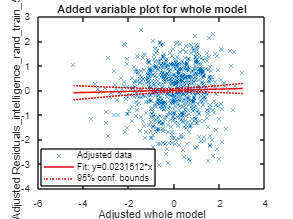

        Model_Matrix = [residuals_pos_train_5 residuals_neg_train_5 residuals_intelligence_train_5_z_rand];
        Model_Matrix = num2cell(Model_Matrix);
        Model_Matrix_table = cell2table(Model_Matrix);
        Model_Matrix_table.Properties.VariableNames = {'residuals_pos_train_5', 'residuals_neg_train_5','Residuals_intelligence_rand_train_5_z'};

        mdl_pos_neg_bcs_train_5_rand = fitlm(Model_Matrix_table);
        plot(mdl_pos_neg_bcs_train_5_rand);

**2) Predict the Intelligence in Test Samples **

**Test Sample 1 **

Convert scores into z-scores

        ALter_test_1_z = normalize(ALter_test_1);
        Gender_test_1_z = normalize(Gender_test_1);
        meanFDJenk_test_1_z = normalize(meanFDJenk_test_1);
        LQ_test_1_z = normalize(LQ_test_1);
        TIV_test_1_z = normalize(TIV_test_1);

        Intelligence_test_1_z = normalize(Intelligence_test_1);


Get the raw residuals by subtracting the fitted values from the observed values (using regression model from above)


        confounds = [ALter_test_1_z Gender_test_1_z meanFDJenk_test_1_z LQ_test_1_z TIV_test_1_z];
        int_pred_test_1 = predict(mdl_regress_train_1_intelligence_rand,confounds);

        residuals_intelligence_test_1_z = (Intelligence_test_1_z - int_pred_test_1);


Retrieve NMAs

        Best_case_scenario_r_values_pos = Best_case_scenario_test_samples{1,1};
        Best_case_scenario_r_values_neg = Best_case_scenario_test_samples{1,2};

Take the Mean per subject

        Positive_all = nanmean(Best_case_scenario_r_values_pos,2);
        Negative_all = nanmean(Best_case_scenario_r_values_neg,2);

        Positive_all = normalize(Positive_all);
        Negative_all = normalize(Negative_all);

Regress out the confounding Variables 

        confounds = [ALter_test_1_z Gender_test_1_z meanFDJenk_test_1_z LQ_test_1_z TIV_test_1_z];


        Positive_all_pred_test_1 = predict(mdl_regress_train_1_pos_bcs,confounds);

        residuals_pos_test_1 = (Positive_all - Positive_all_pred_test_1);


        Negative_all_pred_test_1 = predict(mdl_regress_train_1_neg_bcs,confounds);

        residuals_neg_test_1 = (Negative_all - Negative_all_pred_test_1);

        Xnew = [residuals_pos_test_1 residuals_neg_test_1];
        ypred1_rand = predict(mdl_pos_neg_bcs_train_1_rand,Xnew);

        [r,pval] = corr(ypred1_rand,residuals_intelligence_test_1_z);

Test Sample 2 

Convert scores into z-scores

        ALter_test_2_z = normalize(ALter_test_2);
        Gender_test_2_z = normalize(Gender_test_2);
        meanFDJenk_test_2_z = normalize(meanFDJenk_test_2);
        LQ_test_2_z = normalize(LQ_test_2);
        TIV_test_2_z = normalize(TIV_test_2);

        Intelligence_test_2_z = normalize(Intelligence_test_2);


Get the raw residuals by subtracting the fitted values from the observed values (using regression model from above)

        confounds = [ALter_test_2_z Gender_test_2_z meanFDJenk_test_2_z LQ_test_2_z TIV_test_2_z];
        int_pred_test_2 = predict(mdl_regress_train_2_intelligence_rand,confounds);

        residuals_intelligence_test_2_z = (Intelligence_test_2_z - int_pred_test_2);

Retrieve NMAs

        Best_case_scenario_r_values_pos = Best_case_scenario_test_samples{2,1};
        Best_case_scenario_r_values_neg = Best_case_scenario_test_samples{2,2};

Take the Mean per subject

        Positive_all = nanmean(Best_case_scenario_r_values_pos,2);
        Negative_all = nanmean(Best_case_scenario_r_values_neg,2);

        Positive_all = normalize(Positive_all);
        Negative_all = normalize(Negative_all);

Regress out the confounding Variables 

        confounds = [ALter_test_2_z Gender_test_2_z meanFDJenk_test_2_z LQ_test_2_z TIV_test_2_z];

        Positive_all_pred_test_2 = predict(mdl_regress_train_2_pos_bcs,confounds);

        residuals_pos_test_2 = (Positive_all - Positive_all_pred_test_2);

        Negative_all_pred_test_2 = predict(mdl_regress_train_2_neg_bcs,confounds);

        residuals_neg_test_2 = (Negative_all - Negative_all_pred_test_2);

        Xnew = [residuals_pos_test_2 residuals_neg_test_2];
        ypred2_rand = predict(mdl_pos_neg_bcs_train_2_rand,Xnew);

        [r,pval] = corr(ypred2_rand,residuals_intelligence_test_2_z);

Test Sample 3 

Convert scores into z-scores

        ALter_test_3_z = normalize(ALter_test_3);
        Gender_test_3_z = normalize(Gender_test_3);
        meanFDJenk_test_3_z = normalize(meanFDJenk_test_3);
        LQ_test_3_z = normalize(LQ_test_3);
        TIV_test_3_z = normalize(TIV_test_3);

        Intelligence_test_3_z = normalize(Intelligence_test_3);


Get the raw residuals by subtracting the fitted values from the observed values (using regresion model from above)

        confounds = [ALter_test_3_z Gender_test_3_z meanFDJenk_test_3_z LQ_test_3_z TIV_test_3_z];
        int_pred_test_3 = predict(mdl_regress_train_3_intelligence_rand,confounds);

        residuals_intelligence_test_3_z = (Intelligence_test_3_z - int_pred_test_3);

Retrieve NMAs

        Best_case_scenario_r_values_pos = Best_case_scenario_test_samples{3,1};
        Best_case_scenario_r_values_neg = Best_case_scenario_test_samples{3,2};

Take the Mean per subject

        Positive_all = nanmean(Best_case_scenario_r_values_pos,2);
        Negative_all = nanmean(Best_case_scenario_r_values_neg,2);

        Positive_all = normalize(Positive_all);
        Negative_all = normalize(Negative_all);

Regress out the confounding Variables 

        confounds = [ALter_test_3_z Gender_test_3_z meanFDJenk_test_3_z LQ_test_3_z TIV_test_3_z];

        Positive_all_pred_test_3 = predict(mdl_regress_train_3_pos_bcs,confounds);

        residuals_pos_test_3 = (Positive_all - Positive_all_pred_test_3);

        Negative_all_pred_test_3 = predict(mdl_regress_train_3_neg_bcs,confounds);

        residuals_neg_test_3 = (Negative_all - Negative_all_pred_test_3);

        Xnew = [residuals_pos_test_3 residuals_neg_test_3];
        ypred3_rand = predict(mdl_pos_neg_bcs_train_3_rand,Xnew);


        [r,pval] = corr(ypred3_rand,residuals_intelligence_test_3_z);

Test Sample 4 

Convert scores into z-scores

        ALter_test_4_z = normalize(ALter_test_4);
        Gender_test_4_z = normalize(Gender_test_4);
        meanFDJenk_test_4_z = normalize(meanFDJenk_test_4);
        LQ_test_4_z = normalize(LQ_test_4);
        TIV_test_4_z = normalize(TIV_test_4);

        Intelligence_test_4_z = normalize(Intelligence_test_4);


Get the raw residuals by subtracting the fitted values from the observed values (using regresion model from above)

        confounds = [ALter_test_4_z Gender_test_4_z meanFDJenk_test_4_z LQ_test_4_z TIV_test_4_z];
        int_pred_test_4 = predict(mdl_regress_train_4_intelligence_rand,confounds);

        residuals_intelligence_test_4_z = (Intelligence_test_4_z - int_pred_test_4);

Create the Averages for the People 

        Best_case_scenario_r_values_pos = Best_case_scenario_test_samples{4,1};
        Best_case_scenario_r_values_neg = Best_case_scenario_test_samples{4,2};

Take the Mean per subject

        Positive_all = nanmean(Best_case_scenario_r_values_pos,2);
        Negative_all = nanmean(Best_case_scenario_r_values_neg,2);

        Positive_all = normalize(Positive_all);
        Negative_all = normalize(Negative_all);

Regress out the confounding Variables 

        confounds = [ALter_test_4_z Gender_test_4_z meanFDJenk_test_4_z LQ_test_4_z TIV_test_4_z];

        Positive_all_pred_test_4 = predict(mdl_regress_train_4_pos_bcs,confounds);

        residuals_pos_test_4 = (Positive_all - Positive_all_pred_test_4);

        Negative_all_pred_test_4 = predict(mdl_regress_train_4_neg_bcs,confounds);

        residuals_neg_test_4 = (Negative_all - Negative_all_pred_test_4);

        Xnew = [residuals_pos_test_4 residuals_neg_test_4];
        ypred4_rand = predict(mdl_pos_neg_bcs_train_4_rand,Xnew);


        [r,pval] = corr(ypred4_rand,residuals_intelligence_test_4_z);

Test Sample 5 

Convert scores into z-scores

        ALter_test_5_z = normalize(ALter_test_5);
        Gender_test_5_z = normalize(Gender_test_5);
        meanFDJenk_test_5_z = normalize(meanFDJenk_test_5);
        LQ_test_5_z = normalize(LQ_test_5);
        TIV_test_5_z = normalize(TIV_test_5);

        Intelligence_test_5_z = normalize(Intelligence_test_5);


Get the raw residuals by subtracting the fitted values from the observed values (using regresion model from above)

        confounds = [ALter_test_5_z Gender_test_5_z meanFDJenk_test_5_z LQ_test_5_z TIV_test_5_z];
        int_pred_test_5 = predict(mdl_regress_train_5_intelligence_rand,confounds);

        residuals_intelligence_test_5_z = (Intelligence_test_5_z - int_pred_test_5);

Retrieve NMAs

        Best_case_scenario_r_values_pos = Best_case_scenario_test_samples{5,1};
        Best_case_scenario_r_values_neg = Best_case_scenario_test_samples{5,2};

Take the Mean per subject

        Positive_all = nanmean(Best_case_scenario_r_values_pos,2);
        Negative_all = nanmean(Best_case_scenario_r_values_neg,2);

        Positive_all = normalize(Positive_all);
        Negative_all = normalize(Negative_all);

Regress out the confounding Variables 

        confounds = [ALter_test_5_z Gender_test_5_z meanFDJenk_test_5_z LQ_test_5_z TIV_test_5_z];

        Positive_all_pred_test_5 = predict(mdl_regress_train_5_pos_bcs,confounds);

        residuals_pos_test_5 = (Positive_all - Positive_all_pred_test_5);

        Negative_all_pred_test_5 = predict(mdl_regress_train_5_neg_bcs,confounds);

        residuals_neg_test_5 = (Negative_all - Negative_all_pred_test_5);

        Xnew = [residuals_pos_test_5 residuals_neg_test_5];
        ypred5_rand = predict(mdl_pos_neg_bcs_train_5_rand,Xnew);

        [r,pval] = corr(ypred5_rand,residuals_intelligence_test_5_z);

**3)  Correlate the predicted scores with the actual scores**

        predicted_scores = [ypred1_rand; ypred2_rand; ypred3_rand; ypred4_rand; ypred5_rand];
        actual_scores = [residuals_intelligence_test_1_z; residuals_intelligence_test_2_z; residuals_intelligence_test_3_z; residuals_intelligence_test_4_z; residuals_intelligence_test_5_z];

        [rho_final,pval_final] = corr(predicted_scores,actual_scores);

**4) Save rho_final & pval_final for Permutation Test **

        Permutation_test_all_cross_val_rounds_rho{cross_validation_round,permutation_test_round} = rho_final;
        Permutation_test_all_cross_val_rounds_pval{cross_validation_round, permutation_test_round} = pval_final;

    

**End permutation test **

end
end

## **4. Analysis Section**

all_rhos_final_correlations = cell2mat(cross_validation_100_final_correlation_HCP(:,1))

all_rhos_final_correlations =     0.2260
    0.1812
    0.2147
    0.2030
    0.2079
    0.2092
    0.2122
    0.2098
    0.2296
    0.2095



mean_all_rhos_final_correlations = mean(all_rhos_final_correlations)

mean_all_rhos_final_correlations = 0.2053


Permutation_test_all_cross_val_rounds_rho_mat = cell2mat(Permutation_test_all_cross_val_rounds_rho)

Permutation_test_all_cross_val_rounds_rho_mat =     0.0214    0.0135   -0.0137   -0.1203    0.0199    0.0399   -0.0585   -0.0507    0.0878    0.1416
    0.0386   -0.0225   -0.0709   -0.0328    0.0403   -0.0463    0.0738    0.0204   -0.0108    0.0145
   -0.0754   -0.0236    0.0888    0.0599   -0.0549   -0.0883    0.0409   -0.0415   -0.0441    0.1848
    0.0943   -0.0956    0.0676   -0.0110   -0.0226    0.0603   -0.1035   -0.1393    0.0913   -0.1316
   -0.1516   -0.0511   -0.0629   -0.1119    0.0553   -0.0758    0.0960   -0.0468   -0.0603   -0.0198
    0.0155    0.0293   -0.1293    0.0700    0.0835   -0.1144    0.1289   -0.0775   -0.0953    0.1028
    0.0497    0.1255   -0.0304    0.0887    0.0507    0.0265    0.1103    0.0835    0.1393   -0.0499
   -0.0407   -0.0938   -0.0814   -0.0149   -0.0480    0.0137   -0.0231   -0.0753    0.0063   -0.0249
    0.0651    0.0466    0.0347   -0.0223   -0.0481   -0.0875    0.1060    0.0702    0.0237    0.0643
    0.0409    0.0055   -0.0067   -0.0355   



find(Permutation_test_all_cross_val_rounds_rho_mat > mean_all_rhos_final_correlations)


ans =

  0×1 empty double column vector

